%% Leer datos
T = readtable('angle2.csv');

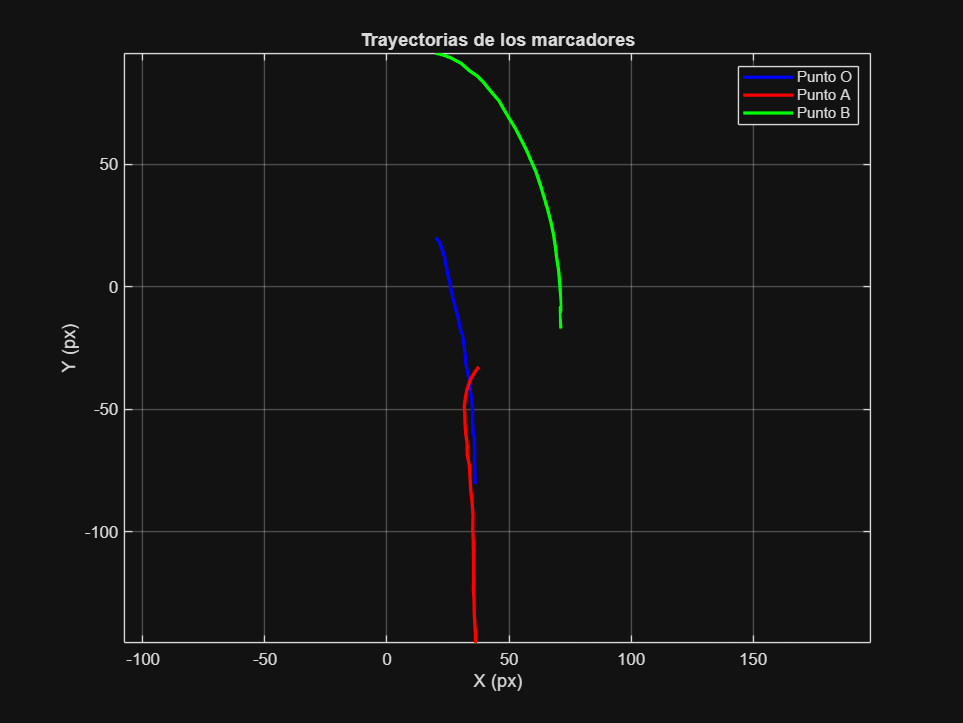


%% Tiempo
t = T.Time;

%% Coordenadas
Ox = T.Angle1_o_0_X;
Oy = T.Angle1_o_0_Y;

Ax = T.Angle1_a_0_X;
Ay = T.Angle1_a_0_Y;

Bx = T.Angle1_b_0_X;
By = T.Angle1_b_0_Y;
%% Animación
figure(Position=[0,0,1200,900])

plot(Ox, Oy, 'b', 'LineWidth', 2)
hold on
plot(Ax, Ay, 'r', 'LineWidth', 2)
plot(Bx, By, 'g', 'LineWidth', 2)

axis equal
grid on

xlabel('X (px)')
ylabel('Y (px)')

title('Trayectorias de los marcadores')

legend('Punto O','Punto A','Punto B')



%ANGLES
OAx = Ax - Ox;
OAy = Ay - Oy;

OBx = Bx - Ox;
OBy = By - Oy;

dotprod = OAx.*OBx + OAy.*OBy; %Producto punto

normOA = sqrt(OAx.^2 + OAy.^2);
normOB = sqrt(OBx.^2 + OBy.^2);
theta = acosd(dotprod ./ (normOA .* normOB))

theta =   161.8288
  161.6094
  161.5129
  160.4249
  160.4267
  160.0962
  160.1028
  158.9762
  157.7374
  157.7273
  157.1402
  156.4942
  156.8914
  155.8746
  155.6300


OAx1 = OAx/cosd(45);
OAy1 = OAy/cosd(45);

OBx1 = OBx/cosd(45);
OBy1 = OBy/cosd(45);

dotprod = OAx1.*OBx1 + OAy1.*OBy1; %Producto punto

normOA1 = sqrt(OAx1.^2 + OAy1.^2);
normOB1 = sqrt(OBx1.^2 + OBy1.^2);
theta1 = acosd(dotprod ./ (normOA1 .* normOB1));

theta1 =   161.8288
  161.6094
  161.5129
  160.4249
  160.4267
  160.0962
  160.1028
  158.9762
  157.7374
  157.7273
  157.1402
  156.4942
  156.8914
  155.8746
  155.6300


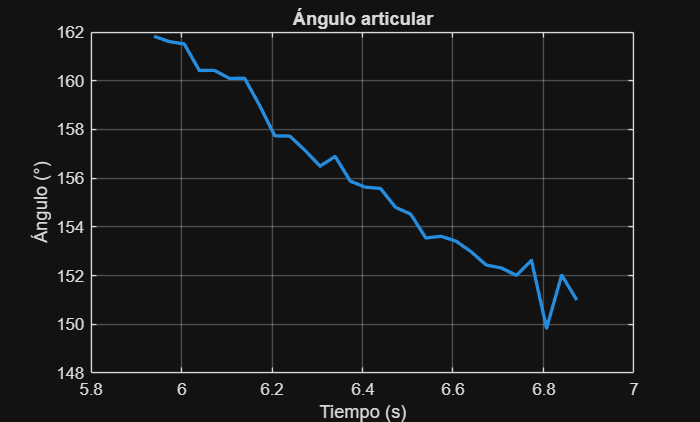


figure;
plot(t,theta,'LineWidth',2)
xlabel('Tiempo (s)')
ylabel('Ángulo (°)')
title('Ángulo articular')
grid on

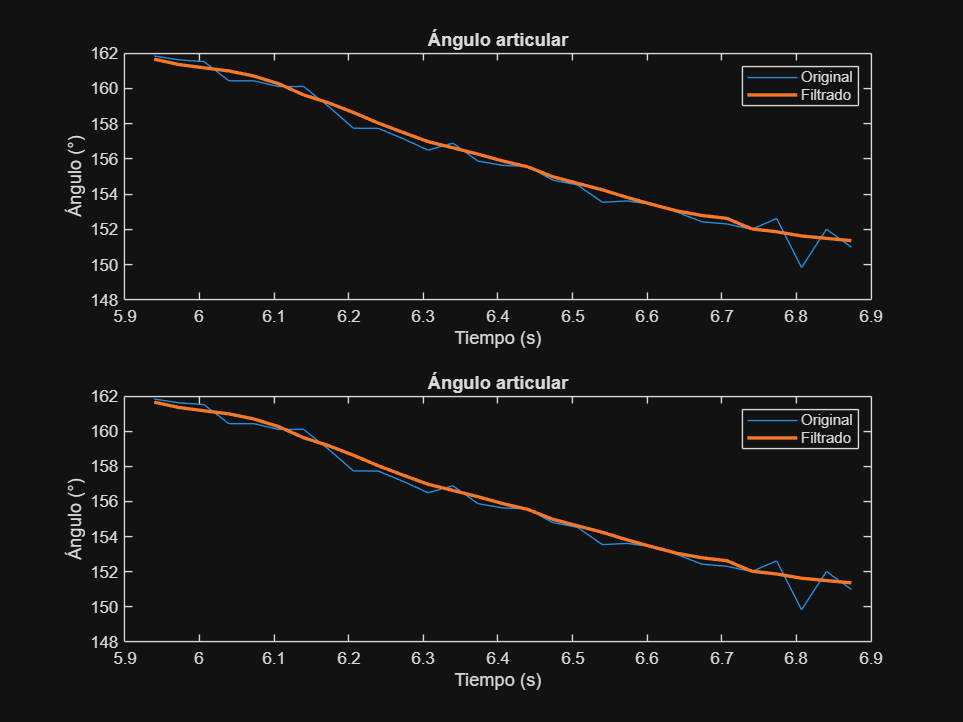


theta_f = smoothdata(theta,'movmean',6);
theta_f1 = smoothdata(theta1,'movmean',6);

figure(Position=[0,0,1200,900]);
subplot(2,1,1);
plot(t,theta);
hold on; plot(t,theta_f,'LineWidth',2); xlabel('Tiempo (s)'); ylabel('Ángulo (°)'); title('Ángulo articular'); legend('Original','Filtrado')
subplot(2,1,2);
plot(t,theta1);
hold on; plot(t,theta_f,'LineWidth',2); xlabel('Tiempo (s)'); ylabel('Ángulo (°)'); title('Ángulo articular cos 45'); legend('Original','Filtrado')